# 1.03.05 Решение нелинейных уравнений

Уравнения, которые содержат переменные, находящиеся в степенях, отличающихся от единицы, или имеющие нелинейные математические выражения (корень, экспонента, логарифм, синус, косинус и т.д.), а также имеющие вид f(x) = 0 называются нелинейными. В зависимости от сложности такого уравнения применяют методы для решения нелинейных уравнений.

## Стандартные функции MATLAB

Для решения нелинейных уравнений в Matlab есть функция `fzero()`. Она принимает в качестве аргументов саму функцию, которую решаем, и отрезок, на котором происходит поиск корней нелинейного уравнения.

Решить нелинейное уравнение $x=e^{-x}$, предварительно определив интервалы, на которых существуют решения уравнения.

Для начала следует привести уравнение к нужному виду: $x-e^{-x} =0$, а затем определить интервалы, в которых будем искать решение уравнения. Методов для определения интервалов множество, но так как пример достаточно прост мы воспользуемся графическим методом.

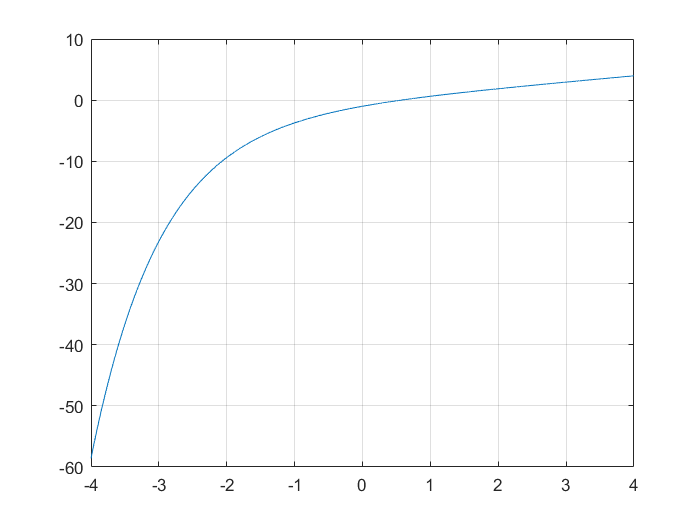

x = -4.0 : 0.001 : 4.0;
y = x - exp(-x);
plot(x,y); grid on;

Из графика видно, что на отрезке [0;1] есть корень уравнения (там, где y = 0), соответственно в дальнейшем будем использовать этот интервал. Чем точнее выбран интервал, тем быстрее метод придет к решению уравнения, а для сложных уравнений правильный выбор интервала определяет погрешность, с которой будет получен ответ.

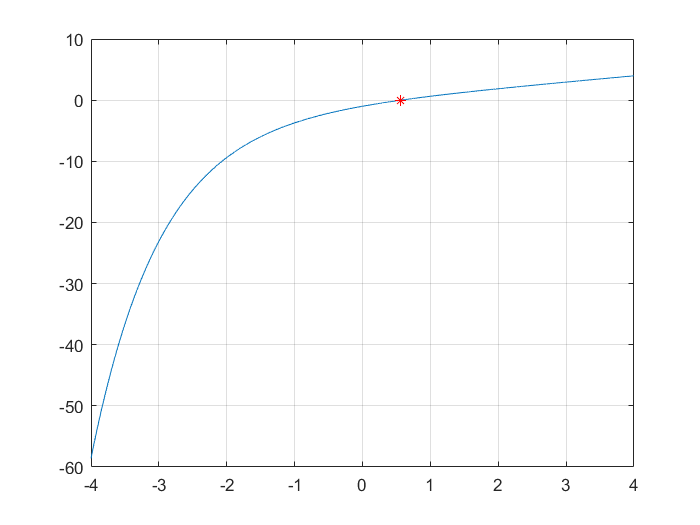

x0 = fzero(@(x)x - exp(-x), [0.0 1.0]);
plot(x,y); grid on; hold on; plot(x0,0,'r*');

Исследуем эту же функцию с помощью других методов и сравним полученные результаты.

## Метод простых итераций

Этот метод заключается в том, что функцию преобразуют к виду: **x = g(x)**. Эти преобразования можно сделать разными способами, в зависимости от вида начальной функции. Помимо этого следует задать интервал, в котором и будет производиться итерационный процесс, а также начальное приближение. Сам процесс строится по схеме **x****n****= g(x****n-1****)**. То есть итерационно проходим от предыдущего значения к последующему, причем задается начальное (нулевое) приближение *x**0*. При известном начальном приближении определяется первое приближение, затем второе, третье и т.д. до тех пор, пока не будет достигнута требуемая точность (т.е. разность между двумя последовательными приближениями не станет пренебрежимо малой).

f = @(x)x - exp(-x);
x0 = 0.0; % начальное приближение
eps = 0.00001; % точность
N = 100; % количество итераций, чтобы не было зацикливаний
g = @(x)exp(-x);
x1 = g(x0); % первое значение
for i = 1 : N % делаем максимум 100 итераций
    if abs(x1 - x0) <= eps
        break
    end
    x0 = x1;
    x1 = g(x0);
end
x1

x1 = 0.5671

i

i = 22

## Метод половинного деления

Метод достаточно прост: существует отрезок поиска решения [a;b], сначала находят значение функции в точке середины **c**, где **c = (a+b)/2**. Затем сравнивают знаки f(a) и f(c). Если знаки разные — то решение находится на отрезке [a;c], если нет — то решение находится на отрезке [c;b]. Таким образом мы сократили область в 2 раза. Такое сокращение происходит и дальше, пока не достигнем заданной точности.

f = @(x)x - exp(-x);
eps = 0.00001;
a = 0.0;
b = 1.0;
i = 0;
while abs(a - b) > eps
    c = (a + b) / 2;
    if ((f(c) * f(a)) < 0)
        b = c;
    else
        a = c;
    end
    i = i + 1;
end
c

c = 0.5671

i

i = 17

## Современные методы решения

fzero(f,[0,1])

ans = 0.5671

Если уравнение задано полиномом, то корни можно найти так:

roots([1 0 -2 -5])

ans =    2.0946 + 0.0000i
  -1.0473 + 1.1359i
  -1.0473 - 1.1359i
